# **Change Identification and Summation From a Photograph**

## Part 1: Image Generation

Whilst any image of US coins would work with this script, we are going to use several default MATLAB images combined in this document, so that no files need to be downloaded. Part 1 covers the combination and formating of this image.

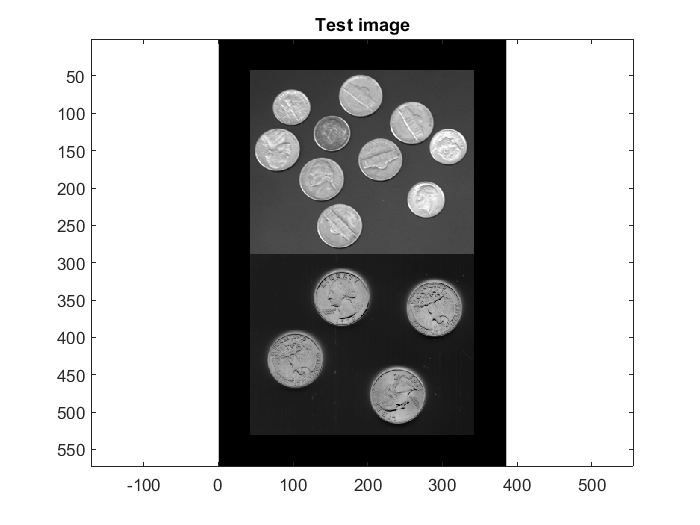

filtsize = 85; %filtsize determines the size of the filter generated. 
% No filters are generated in this section but it is necessary to 
% define it so that several other functions can be defined from it.

% The images to be combined are loaded and their sizes measured
im1 = imread('coins.png');
[r,c] = size(im1);
im2 = imread('eight.tif');
[r2,c2] = size(im2);

%The images are combined and then plotted 
filtsizeh = floor(filtsize/2);
im = zeros(r+r2+filtsize,c+filtsize);
im(filtsizeh+1:filtsizeh+r+r2,filtsizeh+1:filtsizeh+c) = [im1;255-im2(:,1:c)];
[r,c] = size(im);
figure; imagesc(im);colormap(gray);title('Test image');axis equal;

The combined image is then padded with zeros so that the if a filter is applied, there is no danger of it exceding the image dimensions.

## Part 2: Identify Centroids and Simplify Each Coin

The code needs to be able to identify centroids and several other features of the coins, but this cannot be achieved without the image undergoing some processing to simplify it into a more usable form.

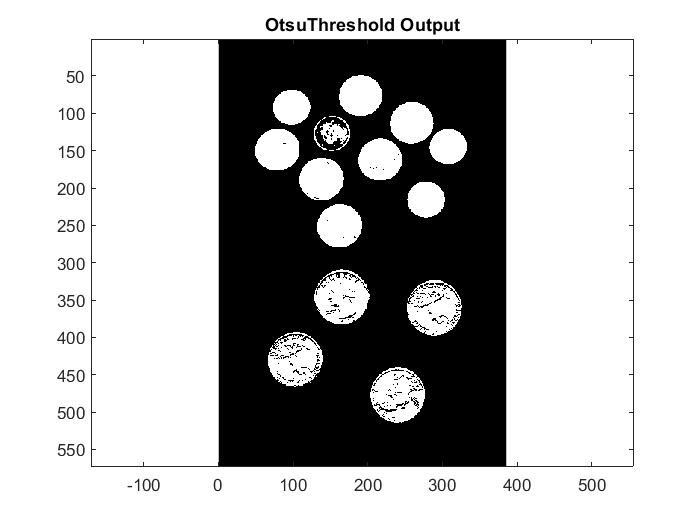

%First we intialise variables that will be needed
msk=[]; msk_dil=[]; msk_dil_erd=[]; centroid=[]; component_size=[];

%To simplify the images we define a function OtsuThreshold, and then call
%it on the image. OtsuThreshold maps all the colours present to a histogram
%and then suggests a  value used to seperate the foreground from the
%background. This value is then converted into the standard 0-255 scale and
%used to form a mask that splits the coins from the background.
msk = OtsuThreshold(im);
figure; imagesc(msk); colormap(gray); title('OtsuThreshold Output'); axis equal;

The foreground and background are now easily distinguishable, however there is still some noise on the surface of the coins that needs to be eliminated using a dilate and then erode function.

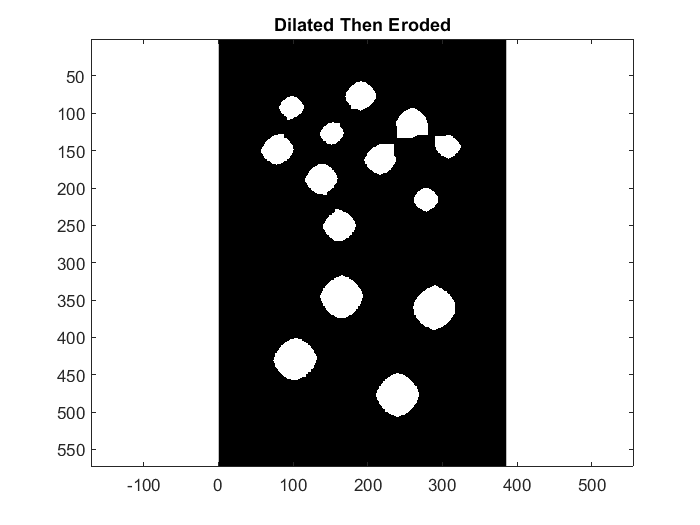

%Dilate averages the img over a 9 by 9 array, and hence removes the
%superfluous detail. However it also increases the size of each coin to the
%extent that some now overlap
msk_dil = imdilate(msk,ones(9,9));

%The img is then eroded to seperate the coins again. The result is plotted.
msk_dil_erd = imerode(msk_dil,ones(23,23));
figure; imagesc(msk_dil_erd); colormap(gray); title('Dilated Then Eroded'); axis equal;

% Now that the image is suitably refined, the properties can be calcuated
% and then indexed, so that the size and centroid of every coin is
% identified
cc = bwconncomp(msk_dil_erd);
props_struct = regionprops(cc);
centroid = zeros(length(props_struct),2);
component_size = zeros(length(props_struct),1);
for i=1:length(props_struct)
    centroid(i,:) = (props_struct(i).Centroid);
    component_size(i) = props_struct(i).Area;
end

## Section 3: Defining Filters

A filter needs to be generated for each type of coin present (quarters, nickels and dimes). A user defined function, MakeCircleMatchingFilter, is used to generate each filter from the diameters of each coin.

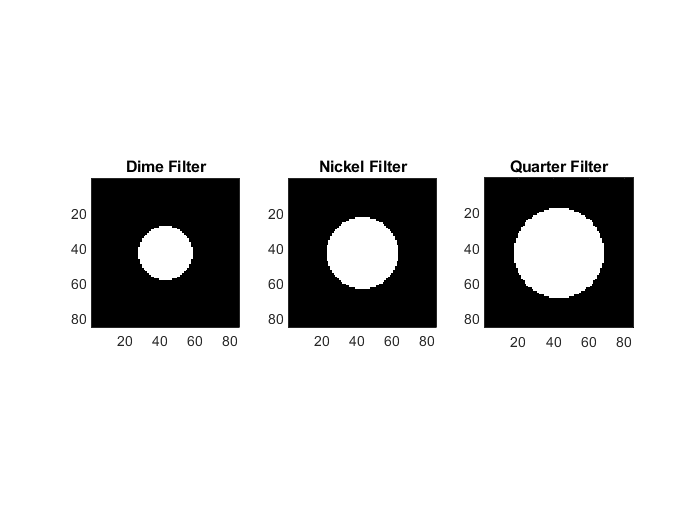

% Define diameters to use for filters
dimediameter = 31;
quarterdiameter = 51;
nickeldiameter = 41;

% Initialise variables 
D=[]; nickelfilter = []; dimefilter = []; quarterfilter = [];

%MakeCircleMatchingFilter sub function just generates a blank array and
%then a circle of the required dimensions on top.
nickelfilter = MakeCircleMatchingFilter(nickeldiameter,filtsize);
dimefilter = MakeCircleMatchingFilter(dimediameter,filtsize);
quarterfilter = MakeCircleMatchingFilter(quarterdiameter,filtsize);

%The figure shows all three filters
figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('Dime Filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('Nickel Filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('Quarter Filter'); axis tight equal;

## Section 4: Clustering and Identifing each Coin

The coins are sorted with a kmeans clustering algorithm into three groups of similar coins. The average size of each group is then analysed to determine which group corresponds to which coin, finally allowing for each individual coin to be identified. Cls contains the correct asignment of each coin.  

% Evaluate each of the 3 matching filters on each coin to serve as 3 feature measurements 
D = zeros(length(centroid),3);
centroid=round(centroid);
for i=1:length(centroid)
    D(i,1) = corr(dimefilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));
    D(i,2) = corr(nickelfilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));
    D(i,3) = corr(quarterfilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));    
end

%Initalise variables
rng(0);
cls_init=[]; cls=[]; totcount=[];
%The coins are then split into three groups by performing a kmeans
%clustering alogirthm. 
cls_init=kmeans(D(:,:),3);

% Relabel centroid classes based on average size of the objects in
% each class. Smallest will be dime, next nickel, and largest quarter
labeled_size=cls_init;
labeled_size(:,2)=component_size(:);
class2=[]; class3=[]; class1=[];
for i=1:length(cls_init)
    if labeled_size(i,1)==1
        class1(end+1)= labeled_size(i,2);
    elseif labeled_size(i,1)==2
        class2(end+1)= labeled_size(i,2);
    else
        class3(end+1)= labeled_size(i,2);
    end
end
average_class_size(1)=mean(class2);
average_class_size(2)=mean(class3);
average_class_size(3)=mean(class1);

for i=1:length(cls_init)
    if labeled_size(i,1)==1
        cls(i)=3;
    elseif labeled_size(i,1)==2
        cls(i)=1;
    else
        cls(i)=2;
    end
end
cls

cls =      2     3     1     2     1     3     2     2     2     3     2     3     1     1


## Section 5: Summation and Plotting

Another user defined function, AddCoinToPlotAndCount, is used to sum the value of the coins and then plot the coins onto the final figure.

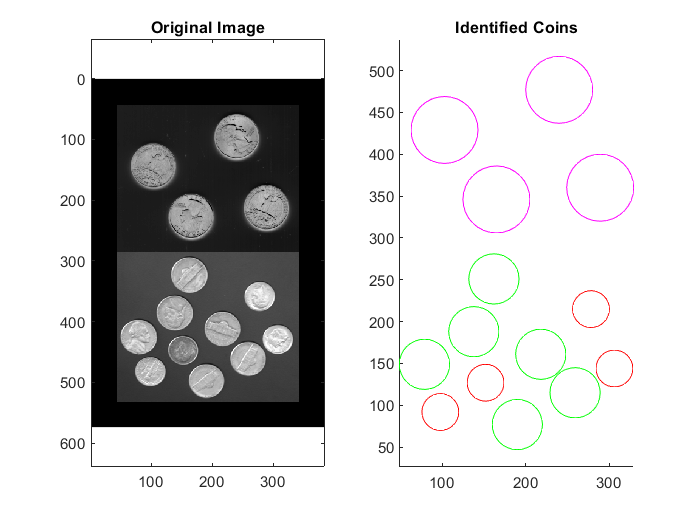

%Initialse vairables
totcount=0;
cls=cls'; %cls is transposed so it can be fed into the function easier
% Visualize the result

figure; subplot(1,2,1); imagesc(imf);colormap(gray);title('Original Image');hold on;axis equal;

% plot circles around each coin with different color/diameter unique to each type and count the change
subplot(1,2,2); hold on; axis equal;
for i=1:length(cls)
    [coinvalue,x_plot,y_plot,col] = AddCoinToPlotAndCount(centroid(i,1),(centroid(i,2)),cls(i));
    totcount=totcount+coinvalue;
    plot(x_plot,y_plot, col)
end
title('Identified Coins')

%Quarters, Nickels and Dimes are magenta, green and red respectuvely.
fprintf('%d cents of change', totcount)

170 cents of change

## Sub Functions

function [msk,thrsh] = OtsuThreshold(im)
    hst = imhist(im);
    res = otsuthresh(hst);
    thrsh = res*255;
    msk = im>thrsh;
end

function filter = MakeCircleMatchingFilter(diameter,filtsize)
filter = zeros(filtsize,filtsize);
radius = diameter/2;
c = (filtsize+1)/2;
for i=1:filtsize
    for j=1:filtsize
        if (i-c)*(i-c) + (j-c)*(j-c) <= radius*radius
            filter(i,j) = 1;
        end
    end
end
end

function [coinvalue,x_plot,y_plot,col] = AddCoinToPlotAndCount(x,y,cls)
% initialize radians for defining x_plot and y_plot using cos and sin functions
rads = 0:2*pi/32:2*pi;
% initialize parameters for radius and color of circle for each type of coin
dimer=22; nickelr=30; quarterr=40;
dimc='red'; nickelc='green'; quarterc='magenta';
dimev=10; nickelv=5; quarterv=25;

if cls==1
    coinvalue=dimev;
    col=dimc;
    x_plot= x+dimer*cos(rads);
    y_plot= y+dimer*sin(rads);
elseif cls==2
    coinvalue=nickelv;
    col=nickelc;
    x_plot= x+nickelr*cos(rads);
    y_plot= y+nickelr*sin(rads);
else 
    coinvalue=quarterv;
    col=quarterc;
    x_plot= x+quarterr*cos(rads);
    y_plot= y+quarterr*sin(rads);
end

end